# Matlab live script for analyzing open field exploration on the Barnes maze.

You will need the following files/data:

- CSV file created by the DLC (centre x and y points required)

- Bonsai XY file created by Bonsai during testing.

- Video file used in the DLC

## Import DLC data

clear all;close all;clc;

% import raw DLC data as a table
[fileName, pathName] = uigetfile('*.csv');

opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [4, Inf];
opts.Delimiter = ",";

% Specify column names and types
%opts.VariableNames = ["scorer","centre_x", "centre_y", "centre_accuracy", "tail_x", "tail_y", "tail_accuracy", "shelter_x", "shelter_y", "shelter_accuracy"];
%opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

opts.VariableNames = ["scorer","centre_x", "centre_y", "centre_accuracy"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
DLCraw = readtable(fullfile(pathName,fileName),opts);

DLCraw = 14457×4 table
    scorer    centre_x    centre_y    centre_accuracy
    ______    ________    ________    _______________

       0       171.68      932.19        0.0015463   
       1      -2.4397     0.98569       1.1623e-05   
       2      -2.4498      0.9811       1.1593e-05   
       3      -2.4491     0.98871       1.1563e-05   
       4       1090.9      502.02          0.94456   
       5       1031.4      124.55          0.99856   
       6       171.46      931.82        0.0036981   
       7       171.36      931.32       3.9369e-05   
       8       171.93      931.89       4.5747e-05   
       9      -2.4597     0.96318       1.1235e-05   
      10      -2.4195      1.0028       1.1355e-05   
      11       -2.433     0.99356       1.1474e-05   
      12      -2.4367     0.99071       1.0818e-05   
      13       -2.464     0.95

clear opts

## Import Bonsai XY

% import bonsai xy data as a table
[fileName, pathName] = uigetfile('*.csv');

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [4, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["timestampmiliseconds", "x", "y"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
BonsaiXY = readtable(fullfile(pathName,fileName),opts);

BonsaiXY = 14453×3 table
    timestampmiliseconds      x         y   
    ____________________    ______    ______

         4.8053e+07         224.64    887.35
         4.8054e+07         224.11    884.95
         4.8054e+07         224.86    886.76
         4.8054e+07         224.78    887.41
         4.8054e+07         224.83    887.46
         4.8054e+07          224.6    887.32
         4.8054e+07         224.52    887.22
         4.8054e+07         224.45    886.82
         4.8054e+07         224.41    887.16
         4.8054e+07         224.63    887.41
         4.8054e+07         224.49     887.3
         4.8054e+07         224.58    887.23
         4.8054e+07         224.55    887.29
         4.8054e+07         224.44    886.99
         4.8054e+07         224.75    887.47
         4.8054e+07         224.83    887.78


clear opts

BonsaiXY.timestamp = (BonsaiXY.timestampmiliseconds(:,1)-BonsaiXY.timestampmiliseconds(1,1))/1000;

BonsaiXY = 14453×4 table
    timestampmiliseconds      x         y       timestamp
    ____________________    ______    ______    _________

         4.8053e+07         224.64    887.35           0 
         4.8054e+07         224.11    884.95    0.031718 
         4.8054e+07         224.86    886.76    0.070912 
         4.8054e+07         224.78    887.41     0.10337 
         4.8054e+07         224.83    887.46     0.13651 
         4.8054e+07          224.6    887.32     0.17066 
         4.8054e+07         224.52    887.22      0.2055 
         4.8054e+07         224.45    886.82     0.24115 
         4.8054e+07         224.41    887.16     0.27668 
         4.8054e+07         224.63    887.41     0.31372 
         4.8054e+07         224.49     887.3     0.34961 
         4.8054e+07         224.58    887.23     0.38418 
         4.8054e+07       

### Equalize the Number of Rows from BonsaiXY and DLCraw to combine both files

% Equalize the row numbers.
Min = min([height(BonsaiXY),height(DLCraw)]);
BonsaiXY = BonsaiXY(1:Min,:);DLCraw = DLCraw(1:Min,:);

DLCraw.timestamp = BonsaiXY.timestamp;

DLCraw = 14453×5 table
    scorer    centre_x    centre_y    centre_accuracy    timestamp
    ______    ________    ________    _______________    _________

       0       171.68      932.19        0.0015463              0 
       1      -2.4397     0.98569       1.1623e-05       0.031718 
       2      -2.4498      0.9811       1.1593e-05       0.070912 
       3      -2.4491     0.98871       1.1563e-05        0.10337 
       4       1090.9      502.02          0.94456        0.13651 
       5       1031.4      124.55          0.99856        0.17066 
       6       171.46      931.82        0.0036981         0.2055 
       7       171.36      931.32       3.9369e-05        0.24115 
       8       171.93      931.89       4.5747e-05        0.27668 
       9      -2.4597     0.96318       1.1235e-05        0.31372 
  


DLCraw = movevars(DLCraw, 'timestamp', "Before", 'scorer');

DLCraw = 14453×5 table
    timestamp    scorer    centre_x    centre_y    centre_accuracy
    _________    ______    ________    ________    _______________

           0        0       171.68      932.19        0.0015463   
    0.031718        1      -2.4397     0.98569       1.1623e-05   
    0.070912        2      -2.4498      0.9811       1.1593e-05   
     0.10337        3      -2.4491     0.98871       1.1563e-05   
     0.13651        4       1090.9      502.02          0.94456   
     0.17066        5       1031.4      124.55          0.99856   
      0.2055        6       171.46      931.82        0.0036981   
     0.24115        7       171.36      931.32       3.9369e-05   
     0.27668        8       171.93      931.89       4.5747e-05   
     0.31372        9      -2.4597     0.96318       1.1235e-05   
  

### Fill in missing low accuracy DLC data

acc_threshold = 0.8;

error_centreIDX = find(DLCraw.centre_accuracy < acc_threshold);
DLCraw.centre_x(error_centreIDX) = NaN;
DLCraw.centre_y(error_centreIDX) = NaN;
DLCraw.centre_x = fillmissing(DLCraw.centre_x,"nearest");
DLCraw.centre_y = fillmissing(DLCraw.centre_y,"nearest");

## Create a timetable with new features.

DLCdata = table(DLCraw.centre_x, DLCraw.centre_y,'VariableNames', {'centre_x', 'centre_y'});
DLCdata.Time = DLCraw.timestamp;

centre = [DLCdata.centre_x DLCdata.centre_y];

clear x y;
v_centre = [];
v_centre(1) = 0;
x = centre(:,1);
y = centre(:,2);
for ii = 2:length(centre)
    v_centre(ii) = pdist([x(ii-1) y(ii-1); x(ii) y(ii)], 'euclidean');
end
v_centre = v_centre';

DLCdata.v_centre = v_centre;

fps = 1/mean(diff(DLCdata.Time));
DLCdata.fps(:) = fps;

DLCdata

DLCdata = 14453×5 table
    centre_x    centre_y      Time      v_centre     fps  
    ________    ________    ________    ________    ______

     1090.9      502.02            0          0     25.911
     1090.9      502.02     0.031718          0     25.911
     1090.9      502.02     0.070912          0     25.911
     1090.9      502.02      0.10337          0     25.911
     1090.9      502.02      0.13651          0     25.911
     1031.4      124.55      0.17066     382.13     25.911
     1031.4      124.55       0.2055          0     25.911
     1031.4      124.55      0.24115          0     25.911
     1031.4      124.55      0.27668          0     25.911
     1031.4      124.55      0.31372          0     25.911
     1031.4      124.55      0.34961          0     25.911
     1031.4      124.55      0.38418  

## Create event to analyze 5 min worth of data:

Selecting 5 min worth of data for analysis corresponding to frames from 10 sec to 5 min 10 sec.

event_X = {};

[~,startrow] = (min(abs(DLCdata.Time - 10)));
[~,endrow] = (min(abs(DLCdata.Time - 310)));
event_X = DLCdata(startrow:endrow,:);

durationevent_X = event_X.Time(end)-event_X.Time(1)

durationevent_X = 299.9703

event_X

event_X = 7785×5 table
    centre_x    centre_y     Time     v_centre     fps  
    ________    ________    ______    ________    ______

     422.16      41.022     10.011       0        25.911
     422.16      41.022     10.048       0        25.911
     422.16      41.022     10.081       0        25.911
     422.16      41.022     10.118       0        25.911
     422.16      41.022     10.155       0        25.911
     422.16      41.022     10.189       0        25.911
     422.16      41.022     10.225       0        25.911
     422.16      41.022     10.263       0        25.911
     422.16      41.022     10.302       0        25.911
     422.16      41.022     10.339       0        25.911
     422.16      41.022     10.373       0        25.911
     422.16      41.022     10.409       0        25.911
     422

## **Define width of one of the holes in pixels and meters**

% Choose the movie file you used in DLC
[MfileName, MpathName] = uigetfile('*.*');
v = VideoReader(fullfile(MpathName,MfileName));

Define boundaries of one hole

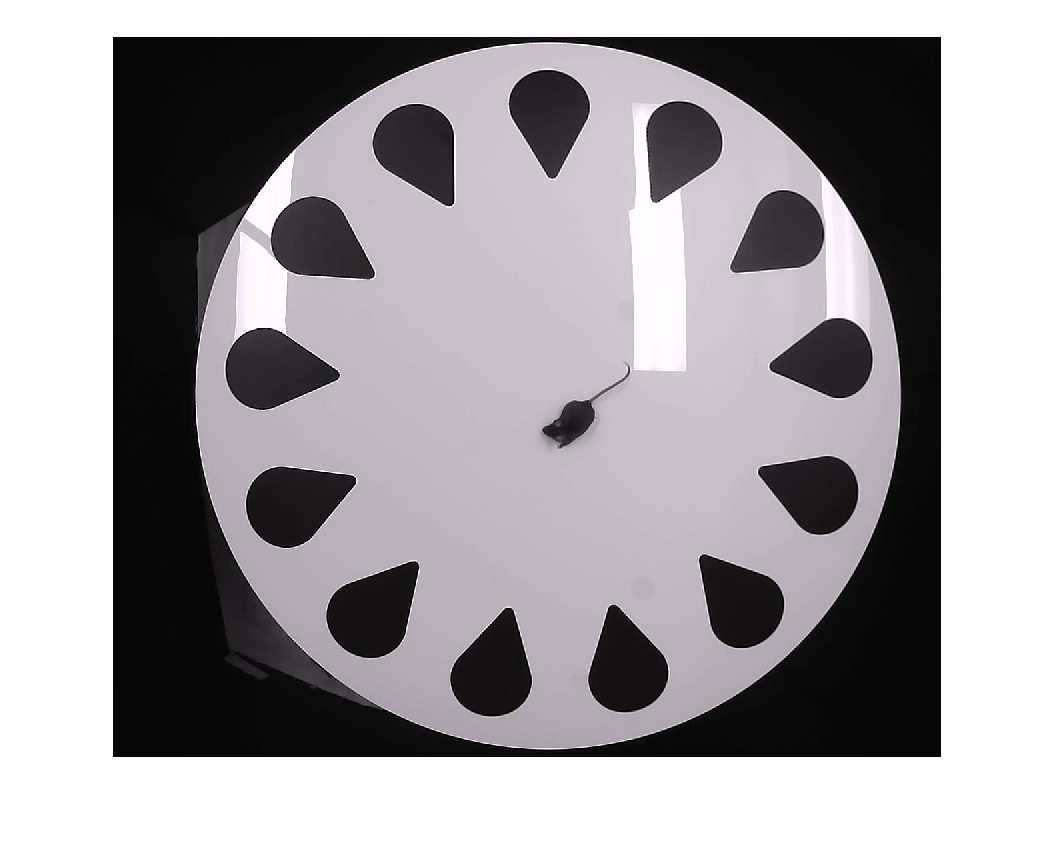

frame = read(v,900); %frame will be used to define the shelter location
imshow(frame);
[shelter_x,shelter_y] = ginput(1); % shelter centre point
ROI = drawcircle('LineWidth',0.5,'StripeColor','cyan','Label','Shelter width');

shelter_r = ROI.Radius; % radius of shelter in pixel.

shelter_r = 84.7633

shelter_d = shelter_r*2

shelter_d = 169.5265

close

## Define the platform boundaries

Define boundaries of the circular platform

frame = read(v,900); %frame will be used to define the shelter location
imshow(frame);
[platform_x,platform_y] = ginput(1);
ROI_platform = drawcircle('LineWidth',0.5,'StripeColor','blue','Label','Platform Zone');

platform_r = ROI_platform.Radius; % radius of roi in pixel.

platform_r = 529.1860

platform_d = ROI_platform.Radius*2; %diameter of roi in pixles

platform_d = 1.0584e+03

inapparatus =inROI(ROI_platform, event_X.centre_x(1:end), event_X.centre_y(1:end));
close

## Correct centre x and centre y data 

### Remove and replace centre_x and centre_y points outside of the apparatus

error = find(inapparatus < 1);
    event_X.centre_x(error) = NaN;
    event_X.centre_y(error) = NaN;

event_X.centre_x = fillmissing(event_X.centre_x,'linear');
event_X.centre_y = fillmissing(event_X.centre_y,'linear');

### Remove and replace outliers for centre_x and centre_y points

centre_x

% fill missing datapoints
    missingcentre_x = fillmissing(event_X.centre_x,'linear');
    event_X.centre_x = missingcentre_x;

% compile corrected DLC tracking data
centre_xcorrected = [];
    centre_xcorrected = filloutliers(event_X.centre_x,'linear', "movmedian" ,[2 2]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.

centre_y

% fill missing datapoints
    missingcentre_y = fillmissing(event_X.centre_y,'linear');
    event_X.centre_y = missingcentre_y;

centre_ycorrected = [];

    centre_ycorrected = filloutliers(event_X.centre_y,'linear', "movmedian" ,[2 2]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.

### Plot corrected centre_x and centre_y data

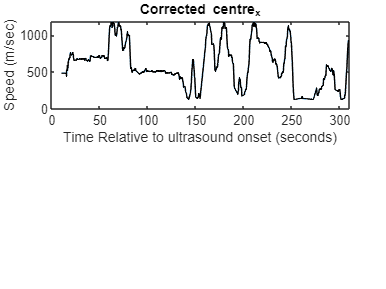

ERF_time = event_X.Time(1:end);
    
figure
subplot(2,1,1)
plot(ERF_time,centre_xcorrected)
title ('Corrected centre_x')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed (m/sec)')
hold on
plot(ERF_time,mean(centre_xcorrected,2),'k','LineWidth',1)

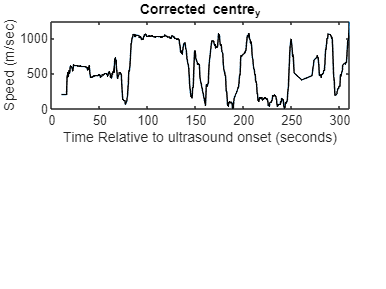


figure
subplot(2,1,1)
plot(ERF_time,centre_ycorrected)
title ('Corrected centre_y')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed (m/sec)')
hold on
plot(ERF_time,mean(centre_ycorrected,2),'k','LineWidth',1)

% Update event variable with corrected position data
event_X.centre_x = centre_xcorrected;
event_X.centre_y = centre_ycorrected;

## Create variable for speed of centre point based on corrected centre x and centre y

centre = [event_X.centre_x event_X.centre_y];

clear x y;
v_centre = [];
v_centre(1) = 0;
x = centre(:,1);
y = centre(:,2);
for ii = 2:length(centre)
    v_centre(ii) = pdist([x(ii-1) y(ii-1); x(ii) y(ii)], 'euclidean');
end
v_centre = v_centre';

event_X.v_centre = v_centre;

### Remove and replace outliers for speed

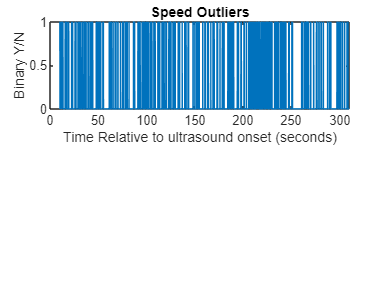

% Fill missing datapoints
missingspeed = fillmissing(event_X.v_centre,'linear');
event_X.v_centre = missingspeed;

% Identify speed outliers
speedoutliers = [];
speedoutliers = isoutlier(event_X.v_centre,"movmedian",[50 50]);

ERF_time = event_X.Time(1:end);
figure
subplot(2,1,1)
plot(ERF_time,speedoutliers)
title ('Speed Outliers')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Binary Y/N')

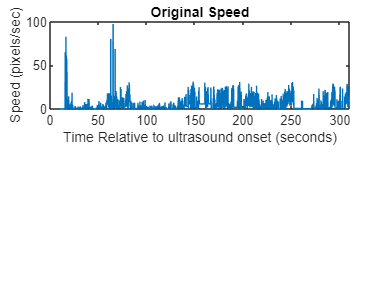


% Compile original DLC tracking data
% Here we are dividing by pixelsperm to get speed in m/s instead of pixels/s
originalspeed =[];
originalspeed = event_X.v_centre;

figure
subplot(2,1,1)
plot(ERF_time,originalspeed)
title ('Original Speed')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed (pixels/sec)')

### Plot corrected speed data

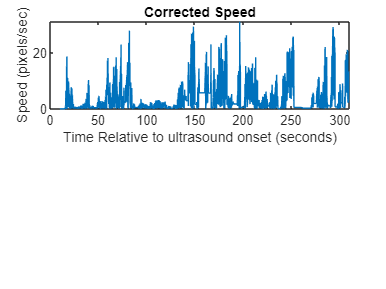

% Compile corrected DLC tracking data
speedcorrected = [];
speedcorrected = filloutliers(event_X.v_centre,'linear', "movmedian" ,[50 50]);
% Speed is divided by pixelsperm to convert from pixels/sec to m/sec
% "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
% "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
% This method is also known as a Hampel filter.

figure
subplot(2,1,1)
plot(ERF_time,speedcorrected)
title ('Corrected Speed')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed (pixels/sec)')

### Convert speed data from pixels/sec to meters/sec

% Determine how many pixels per m in the video
% The radius of the defined shelter outlined in the video is equilavent to 15.3cm = 0.153m.
% Dividing the shelter radius in pixels by the shelter radius in meters will give you the number of pixels per meter.
pixelsperm = shelter_d/0.153;
speedmeterspersec = speedcorrected/pixelsperm;

max_speed = max(speedmeterspersec); % find the max speed in meters/sec
distance_travelled_meters = sum(speedmeterspersec); % total distance travelled in meters
average_speed = mean(speedmeterspersec); % average speed in meters/sec

## Compile parameters

compileddata = []


compileddata =

     []



compileddata.max_speed = max_speed

compileddata = struct with fields:
    max_speed: 0.0279


compileddata.distance_travelled_meters = distance_travelled_meters

compileddata = struct with fields:
                    max_speed: 0.0279
    distance_travelled_meters: 21.7034


compileddata.average_speed = average_speed

compileddata = struct with fields:
                    max_speed: 0.0279
    distance_travelled_meters: 21.7034
                average_speed: 0.0028


## Plot locomotion trajectory on Barnes maze

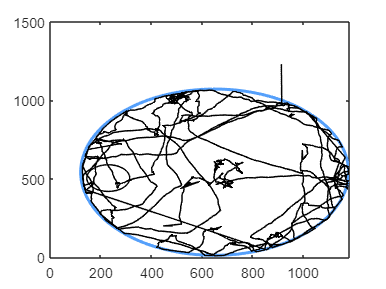

% Rename variables to plot
xc_platform = platform_x;
yc_platform = platform_y;
r_platform = platform_r;

% Create outline of the platform
figure
    theta = linspace(0,2*pi);
    x_platform = r_platform*cos(theta) + xc_platform;
    y_platform = r_platform*sin(theta) + yc_platform;
    plot(x_platform,y_platform,'color', "#55A0FB", 'linewidth', 2)
    hold on

% add body position to plot
theta = linspace(0,2*pi);
    x_centre = centre_xcorrected;
    y_centre = centre_ycorrected;
    plot(x_centre,y_centre, "black", 'linewidth', 1)
    hold on

## Save the entire workspace as a mat file

uisave